tic;
% Membaca dataset
data = readtable('iris.data.csv');
input = table2array(data(:, 1:end-1)); % Asumsikan kolom terakhir adalah label
labels = data{:, end}; % Gunakan kurung kurawal untuk mengakses data dalam tabel

% Konversi label teks menjadi angka
uniqueLabels = unique(labels);
target = zeros(height(data), 1);
for i = 1:length(uniqueLabels)
    target(strcmp(labels, uniqueLabels{i})) = i;
end

% Normalisasi data
input = (input - min(input)) ./ (max(input) - min(input));

% Membagi dataset menjadi training dan testing dengan Stratified Sampling
ratio = 0.1;
uniqueTargets = unique(target);
trainIdx = [];
testIdx = [];

for i = 1:length(uniqueTargets)
    classIdx = find(target == uniqueTargets(i)); % Indeks dari kelas tertentu
    numTrainClass = round(ratio * length(classIdx));
    
    randClassIdx = randperm(length(classIdx));
    
    trainClassIdx = classIdx(randClassIdx(1:numTrainClass));
    testClassIdx = classIdx(randClassIdx(numTrainClass+1:end));
    
    trainIdx = [trainIdx; trainClassIdx];
    testIdx = [testIdx; testClassIdx];
end

inputTrain = input(trainIdx, :);
targetTrain = target(trainIdx);
inputTest = input(testIdx, :);
targetTest = target(testIdx);

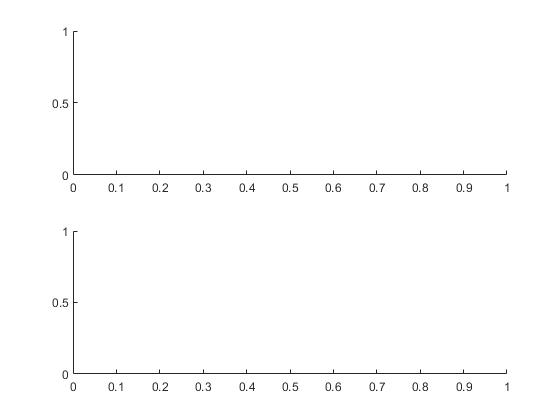


% Inisialisasi Jaringan
alpha = 0.4; %kecepatan learning
miu = 0.75; %momentum learning
n = size(inputTrain, 2); % Jumlah fitur
m = 10; % Jumlah neuron di hidden layer
l = length(unique(targetTrain)); % Jumlah kelas
max_epoch = 10000;
EP = inf;

% Inisialisasi untuk menyimpan hasil dari setiap iterasi
allEpochs = zeros(1000, 1);
allAccuracies = zeros(1000, 1);
allPredictedLabels = [];
allTargetTest = [];
iterations = 1:1000;
epochs = zeros(1, 1000);
accuracies = zeros(1, 1000);

% Membuat figure untuk grafik
figure;
h1 = subplot(2,1,1); % Untuk grafik epoch
h2 = subplot(2,1,2); % Untuk grafik akurasi

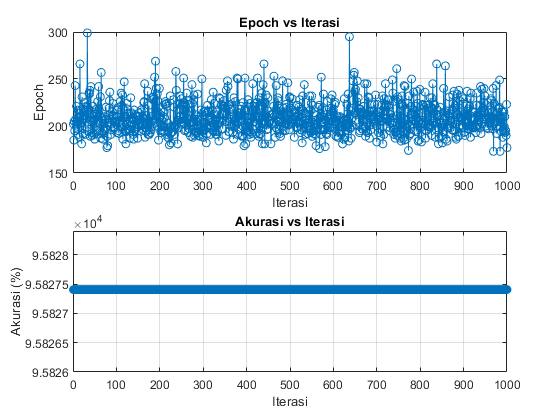

% Mulai iterasi
for iteration = 1:1000
    % Reset epoch dan EP untuk setiap iterasi
    epoch = 0;
    EP = inf;
    % Inisialisasi bobot dan bias dengan Nguyen-Widrow
    beta = 0.7 * m^(1/n);
    v = rand(n, m) * 2 - 1;
    normV = sqrt(sum(v.^2));
    v = beta * v ./ normV;
    v0 = (rand(1, m) * 2 - 1) * beta;
    w = rand(m, l) * 2 - 1;
    w0 = rand(1, l) * 2 - 1;

    %inisialiasi momentum perubahan bobot
    deltaWPrev = zeros(size(w));
    deltaVPrev = zeros(size(v));
    deltaW0Prev = zeros(size(w0));
    deltaV0Prev = zeros(size(v0));
    
    epoch = 0;
    previousEP = 0; %untuk kebutuhan grafik realtime
    errorList = []; % Untuk menyimpan error pada setiap epoch

    while EP > 0.01 && epoch < max_epoch
        EP = 0;
        for p = 1:size(inputTrain, 1)
            xi = inputTrain(p, :);
            tk = zeros(1, l);
            tk(targetTrain(p)) = 1;
    
            % Feedforward
            z_in = zeros(1, m);
            z = zeros(1, m);
            for j = 1:m
                z_in(j) = xi * v(:, j) + v0(j);
                z(j) = 1 / (1 + exp(-z_in(j)));
            end
            
            y_in = zeros(1, l);
            y = zeros(1, l);
            for k = 1:l
                y_in(k) = z * w(:, k) + w0(k);
                y(k) = 1 / (1 + exp(-y_in(k)));
            end
            
            % Backpropagation
            delta_k = zeros(1, l);
            for k = 1:l
                delta_k(k) = (tk(k) - y(k)) * y(k) * (1 - y(k));
            end
            
            delta_j = zeros(1, m);
            for j = 1:m
                sum_delta_w = 0;
                for k = 1:l
                    sum_delta_w = sum_delta_w + delta_k(k) * w(j, k);
                end
                delta_j(j) = sum_delta_w * z(j) * (1 - z(j));
            end
    
            % Update bobot dan bias dengan momentum
            for k = 1:l
                for j = 1:m
                    deltaW = alpha * delta_k(k) * z(j);
                    w(j, k) = w(j, k) + deltaW + miu * deltaWPrev(j, k);
                    deltaWPrev(j, k) = deltaW;
                end
                deltaW0 = alpha * delta_k(k);
                w0(k) = w0(k) + deltaW0 + miu * deltaW0Prev(k);
                deltaW0Prev(k) = deltaW0;
            end
            
            for j = 1:m
                for i = 1:n
                    deltaV = alpha * delta_j(j) * xi(i);
                    v(i, j) = v(i, j) + deltaV + miu * deltaVPrev(i, j);
                    deltaVPrev(i, j) = deltaV;
                end
                deltaV0 = alpha * delta_j(j);
                v0(j) = v0(j) + deltaV0 + miu * deltaV0Prev(j);
                deltaV0Prev(j) = deltaV0;
            end
    
    
            EP = EP + sum((tk - y).^2)/2;
    
        end
        EP = EP / size(inputTrain, 1);
        epoch = epoch + 1;
        errorList = [errorList, EP]; % Menambahkan error ke list
    end
    
    % Evaluasi pada dataset training
    correctTrain = 0;
    predictedLabelsTrain = zeros(size(inputTrain, 1), 1);
    for p = 1:size(inputTrain, 1)
        xi = inputTrain(p, :);
        tk = zeros(1, l);
        tk(targetTrain(p)) = 1;
    
        % Feedforward
        z_in = zeros(1, m);
        z = zeros(1, m);
        for j = 1:m
            for i = 1:n
                z_in(j) = z_in(j) + xi(i) * v(i, j);
            end
            z_in(j) = z_in(j) + v0(j);
            z(j) = 1 / (1 + exp(-z_in(j)));
        end
        
        y_in = zeros(1, l);
        y = zeros(1, l);
        for k = 1:l
            for j = 1:m
                y_in(k) = y_in(k) + z(j) * w(j, k);
            end
            y_in(k) = y_in(k) + w0(k);
            y(k) = 1 / (1 + exp(-y_in(k)));
        end
    
        [~, predicted] = max(y);
        predictedLabelsTrain(p) = predicted;
        if predicted == targetTrain(p)
            correctTrain = correctTrain + 1;
        end
    end
        accuracy = correct / size(inputTest, 1) * 100; % Hitung akurasi

    % Simpan hasil dari iterasi ini
    allEpochs(iteration) = epoch;
    allAccuracies(iteration) = accuracy;
    allPredictedLabels = [allPredictedLabels; predictedLabels];
    allTargetTest = [allTargetTest; targetTest];
  
       % Pembaruan data
    epochs(iteration) = epoch;
    accuracies(iteration) = accuracy;
    
    % Tampilkan grafik epoch
    subplot(h1);
    plot(iterations(1:iteration), epochs(1:iteration), '-o');
    title('Epoch vs Iterasi');
    xlabel('Iterasi');
    ylabel('Epoch');
    grid on;
    
    % Tampilkan grafik akurasi
    subplot(h2);
    plot(iterations(1:iteration), accuracies(1:iteration), '-o');
    title('Akurasi vs Iterasi');
    xlabel('Iterasi');
    ylabel('Akurasi (%)');
    grid on;
    
    drawnow; % Memperbarui tampilan grafik
end


elapsedTime = toc; % Dapatkan waktu yang telah berlalu
fprintf('Total Elapsed Time: %.2f seconds\n', elapsedTime);

Total Elapsed Time: 152.68 seconds


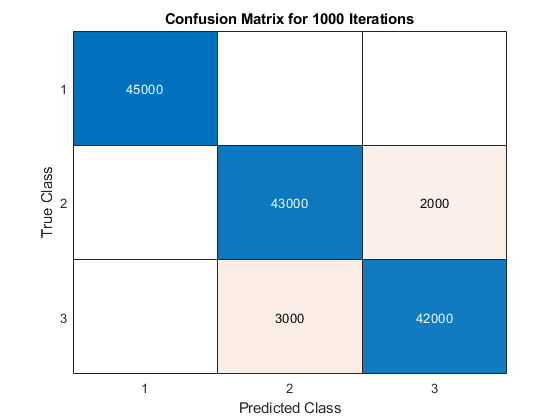

% Hitung rata-rata dari semua epoch dan akurasi
avgEpoch = mean(allEpochs);
avgAccuracy = mean(allAccuracies);

% Menampilkan Confusion Matrix dari semua iterasi
figure;
confusionchart(allTargetTest, allPredictedLabels);
title('Confusion Matrix for 1000 Iterations');

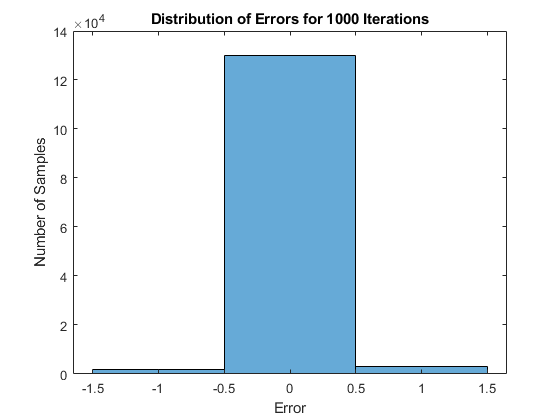


% Menampilkan Distribusi Kesalahan dari semua iterasi
errors = allTargetTest - allPredictedLabels;
figure;
histogram(errors);
title('Distribution of Errors for 1000 Iterations');
xlabel('Error');
ylabel('Number of Samples');


% Menghitung dan menampilkan akurasi keseluruhan
correct = sum(allTargetTest == allPredictedLabels);
accuracy = correct / length(allTargetTest) * 100;
disp(['Akurasi pada dataset testing untuk 1000 iterasi: ' num2str(accuracy) '%']);

Akurasi pada dataset testing untuk 1000 iterasi: 96.2963%
